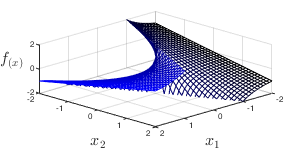

clear

x1 = -2:0.1:2;
x2 = -2:0.1:2;


y = zeros(length(x1));

for i = 1:length(x1)
    for j = 1:length(x2)
        y(i,j) = x1(i)/x2(j);
    end    
end

CO(:,:,1) = zeros(length(x1)); % red
CO(:,:,2) = zeros(length(x1)); % green
CO(:,:,3) = ones(length(x1)).*linspace(0,1,length(x1)); % blue
f = figure();
mesh(x1,x2,y,CO);
zlim([-2,2]);
view(135,45);
ax = gca; 
ax.FontSize = 6; 

xlabel("$$x_1$$","FontSize",12,'Interpreter','latex');
ylabel("$$x_2$$","FontSize",12,'Interpreter','latex');
zlabel("$$f_{(x)}$$","FontSize",12,'Interpreter','latex',"Rotation",0,"Position",[+2.455,-2.455,0] );
f.Units = "pixels";
f.Position = [0,0,300,150];

exportgraphics(f,"divide_e.png");

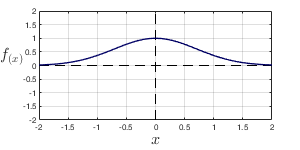


% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 
% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 
f1 = figure();
x = -2:0.1:2;




% % % % % % % % % % % % % % % % % % % % % % % % % % % % % %
nazev1 = "rad";


y = 1./(exp(x.^2));
% y(y>1) = 1;
% y(y<0) = 0;
% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 
plot([-2,2],[0,0],"k--");
hold on;
grid on;
xticks(-2:0.5:2);
yticks(-2:0.5:2);
plot([0,0],[-2,2],"k--");

plot(x,y,"LineWidth",1.,"Color",'#000064');

% plot(x(1:21),zeros(1,21),"LineWidth",1.,"Color",'#000064');
% plot(x(21:41),ones(1,21),"LineWidth",1.,"Color",'#000064');
% plot(0,1,"o","LineWidth",1,"Color",'#000064','MarkerFaceColor','#000064');
% plot(0,0,"o","LineWidth",1,"Color",'#000064');

xlim([-2 2])
ylim([-2 2])
ax = gca; 
ax.FontSize = 6; 
xlabel("$$x$$","FontSize",12,'Interpreter','latex');
ylabel("$$f_{(x)}$$","FontSize",12,'Interpreter','latex',"Rotation",0,"Position",[-2.455,0]);

f1.Units = "pixels";
f1.Position = [0,0,300,150];

exportgraphics(f1,strcat(nazev1,"_e.png"));